# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_slcm.mlx
    ------------
    This code solves firm's investment problem.

%}

## Model: Model of Firm Investment.

The representative firm is infinitely lived. It maximizes the present value of its lifetime profit by choosing capital investment subject to a convex cost of adjustment. The dynamic programming problem associated with this is:


$$V(A,K,p) = \underset{i}{\text{max}} \ AK^{\alpha} - \frac{\gamma}{2}\left(\frac{i}{K}\right)^2K - pi + \beta \mathbb{E}\left[V(A',K',p)\right] \ ,$$



$$\text{s.t. } \ \text{log} \ A' = \mu + \rho \ \text{log} \ A + \epsilon' \ ,$$



$$K' = (1-\delta)K + i  \ , $$


where $p$ is the price of investment, $|\rho|<1$ and $\epsilon'\sim\mathcal{N}(0,\sigma^2)$. Substituting the law of motion gives


$$V(A,K,p) = \underset{K'}{\text{max}} \ AK^{\alpha} - \frac{\gamma}{2}\left(\frac{K' - (1-\delta)K}{K}\right)^2K - p(K' - (1-\delta)K) + \beta \mathbb{E}\left[V(A',K',p)\right] \ ,$$



$$\text{s.t. } \ \text{log} \ A' = \mu + \rho \ \text{log} \ A + \epsilon' \ .$$


## Set up directories and paths.

clc
clear
close all

main = strcat('C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Firms Modelling'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Firms Modelling 



## Set the parameters and generate the state space.

Calls: model.m.

The grid for assets is set exogenously.

par1 = model1.setup; % Set parameters.
par1 = model1.gen_grids(par1); % Generate the state space.

## Solve the model using Value Function iteration.

We will solve the model using value function iteration. Our guess is that firm value is zero over the state space.


$$V(A,K) = 0 \ .$$


### Solve, Simulate & Plot 1a for large firms ($n=936$)

Calls: solve1.m, simulate1.m and my_graph1.m.

Simulate a single firm over time.

t = cputime;
sol1 = solve1.firm_problem(par1); % Solve the model using Value Function Iteration.

------------Beginning Value Function Iteration.------------

Iteration: 25

Converged in 42 iterations.

------------End of Value Function Iteration.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 21.3906 seconds.


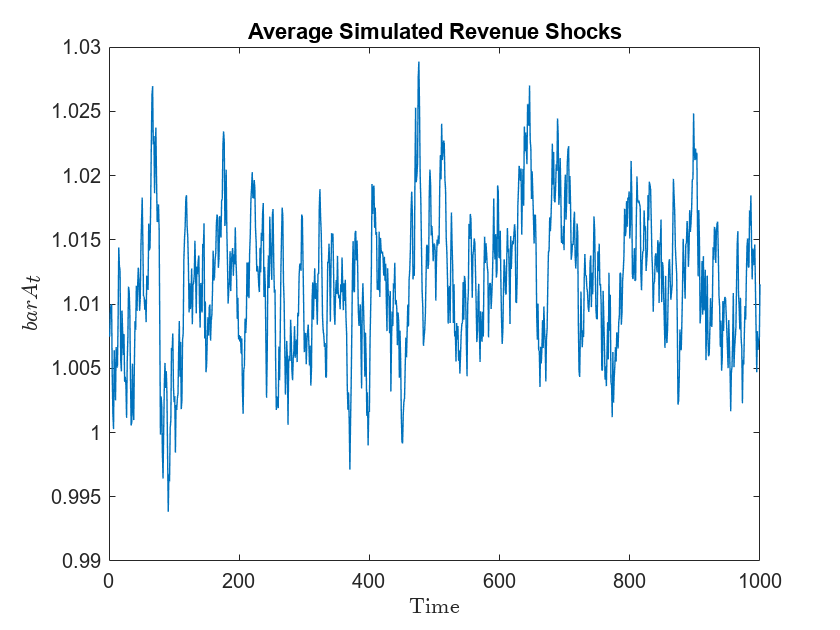

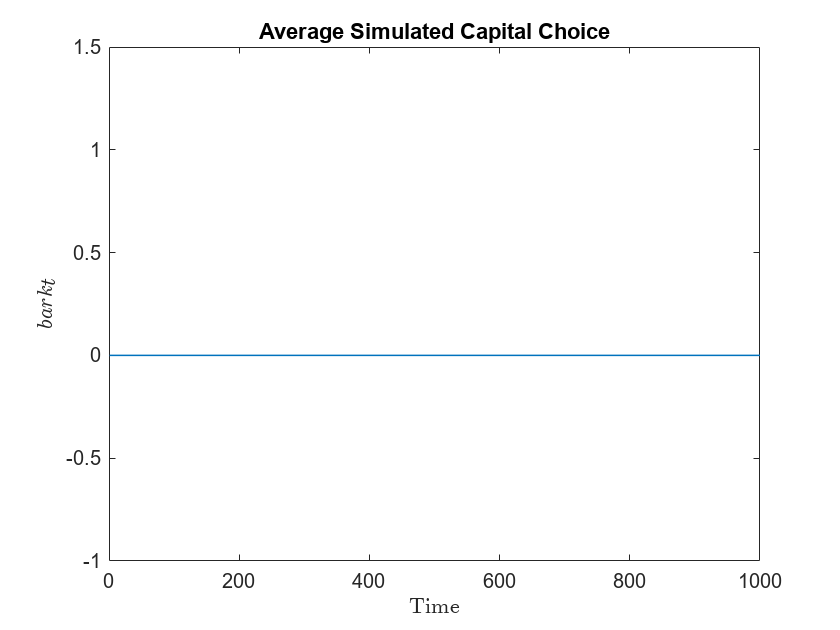

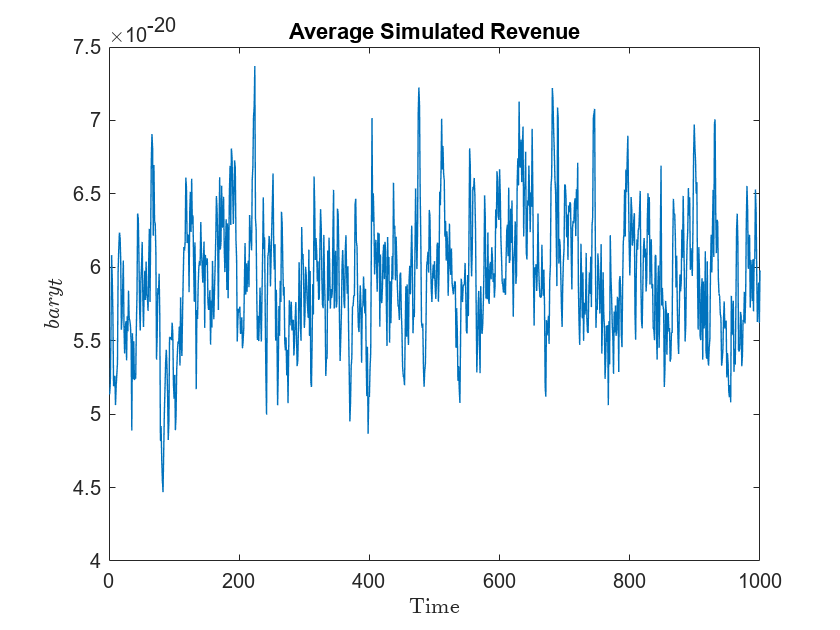

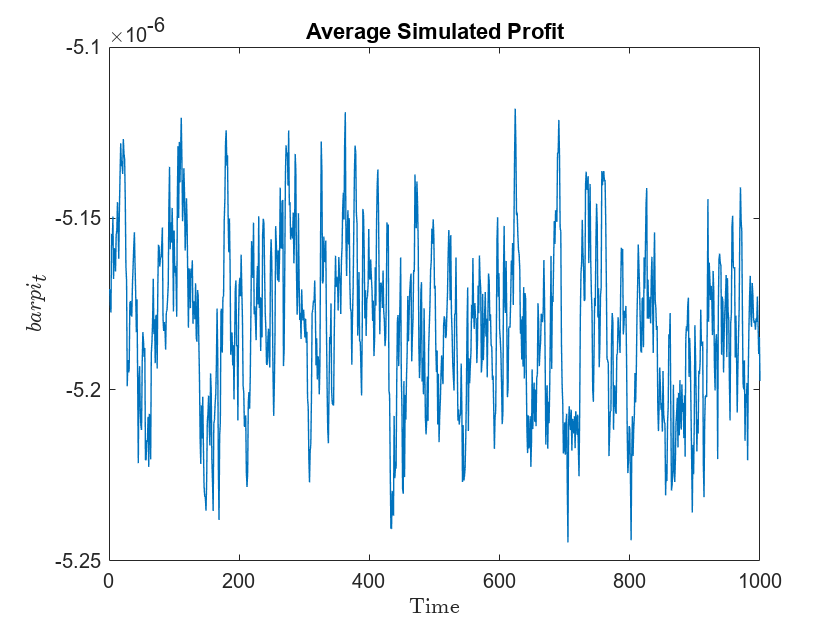

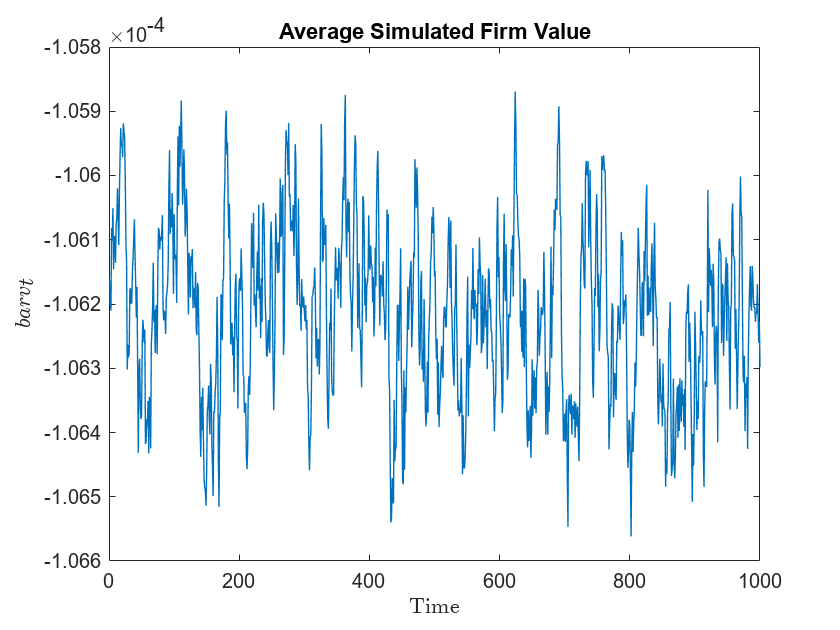

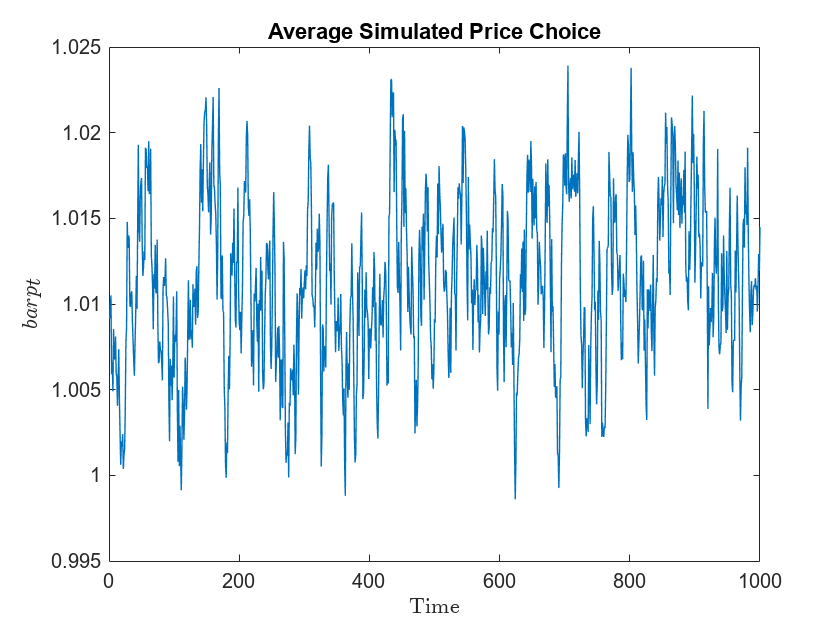

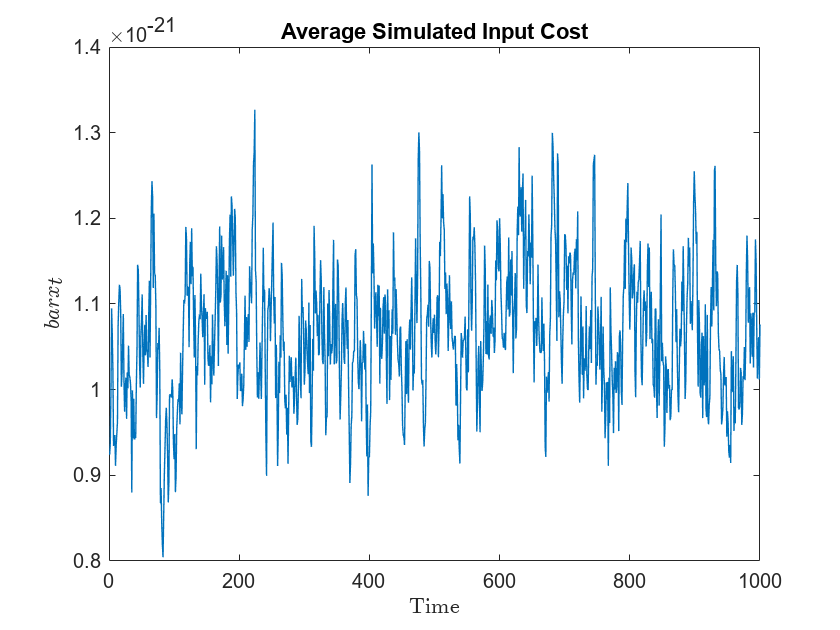

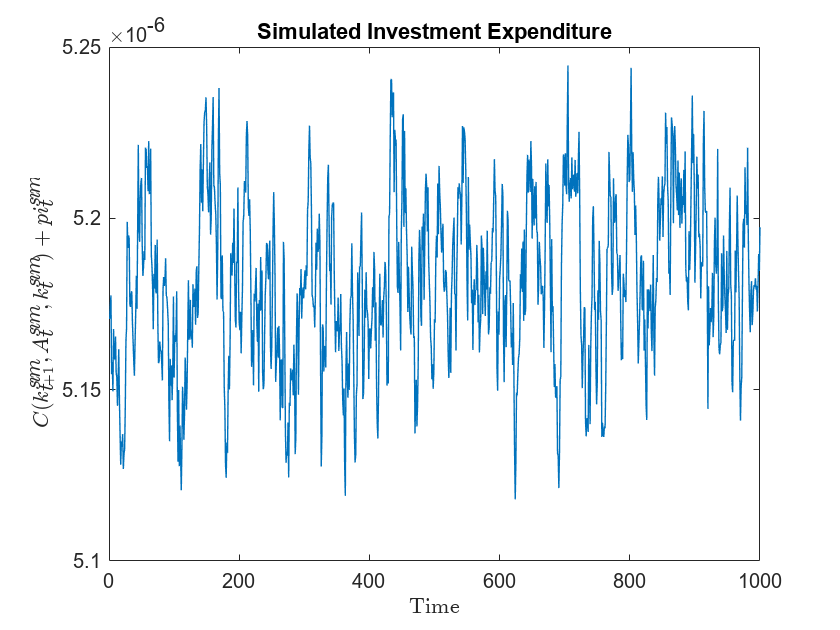

sim1 = simulate1.firm_dynamics(par1,sol1); % Simulate the model.
my_graph1.plot_policy(par1, sim1, figout, 'large_')

%my_graph1.plot_policy_3D(par1, sol1, figout, 'large_')

## Set the parameters and generate the state space.

Calls: model.m.

The grid for assets is set exogenously.

nsmall = 1106;
par_small = par1; % Create a copy of the parameters
par_small.nlarge = nsmall;

## Solve the model using Value Function iteration.

We will solve the model using value function iteration. Our guess is that firm value is zero over the state space.


$$V(A,K) = 0 \ .$$


### Solve, Simulate & Plot 1a for small firms ($n=1106$)

Calls: solve1.m, simulate1.m and my_graph1.m.

t = cputime;
sol_small = solve1.firm_problem(par_small); % Solve the model using Value Function Iteration.

------------Beginning Value Function Iteration.------------

Iteration: 25

Converged in 42 iterations.

------------End of Value Function Iteration.------------


sim_small = simulate1.firm_dynamics(par_small,sol_small); % Simulate the model.
fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 20.9531 seconds.


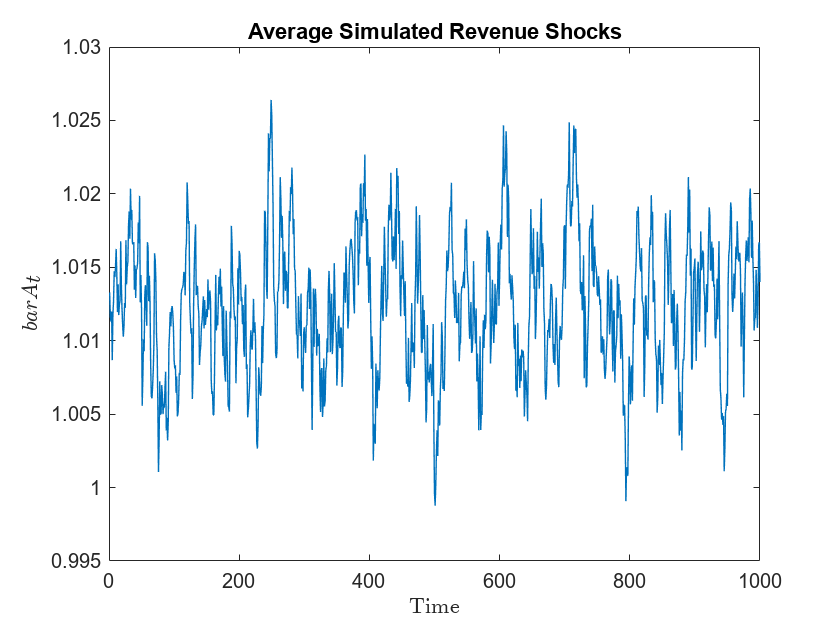

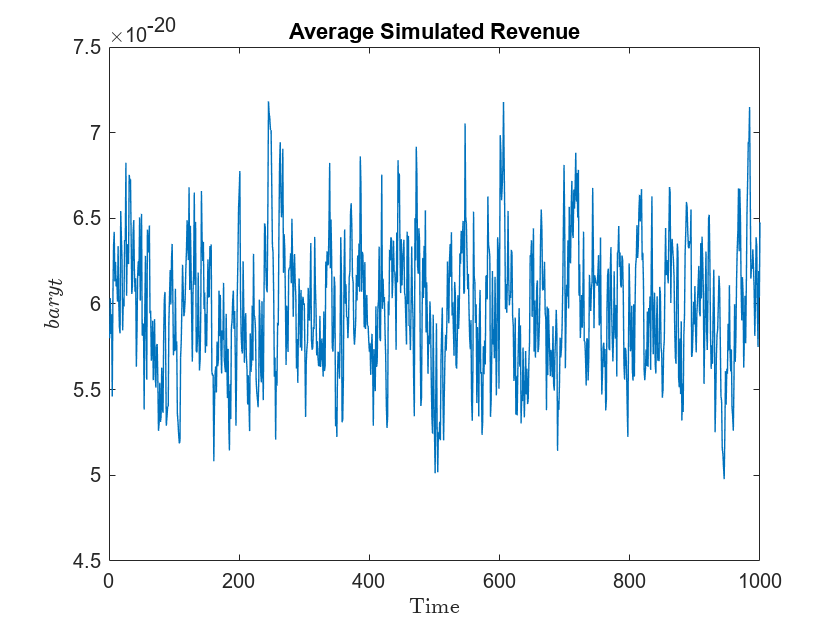

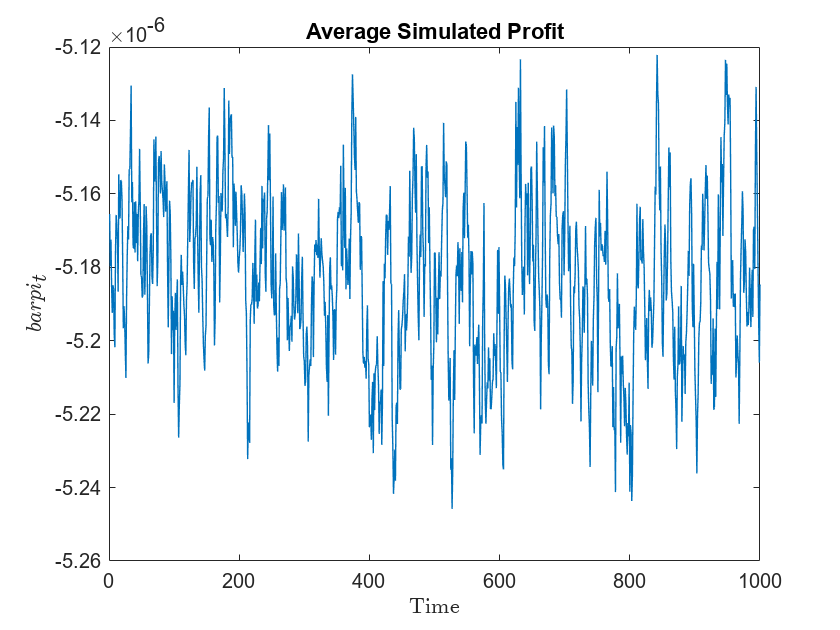

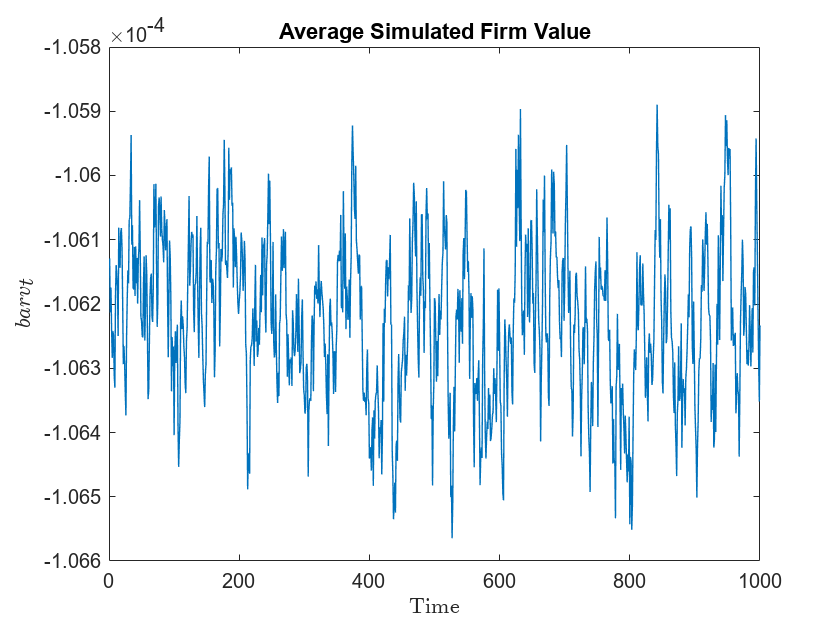

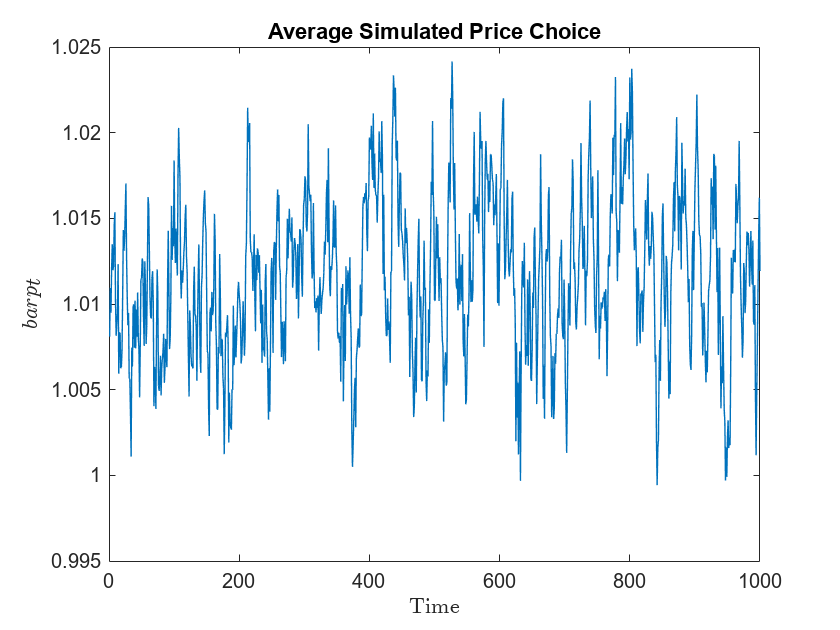

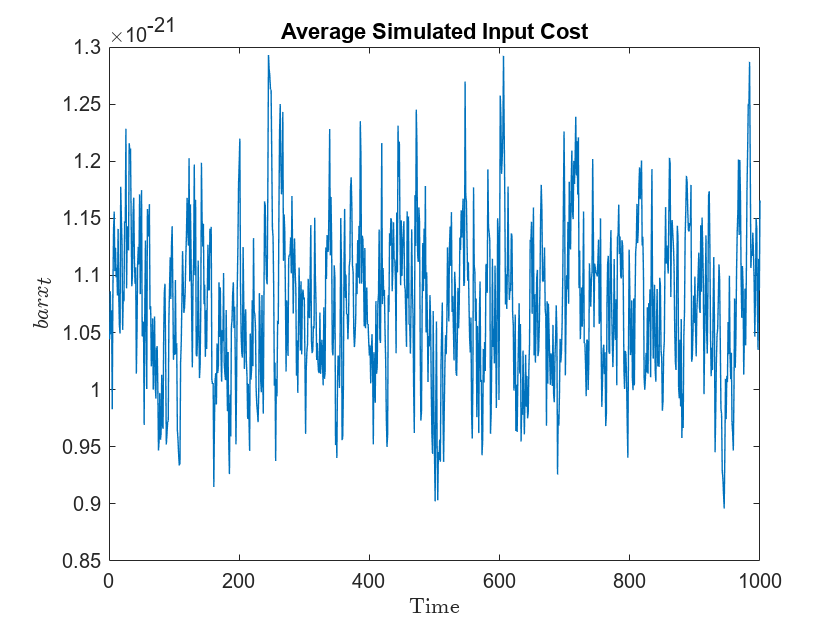

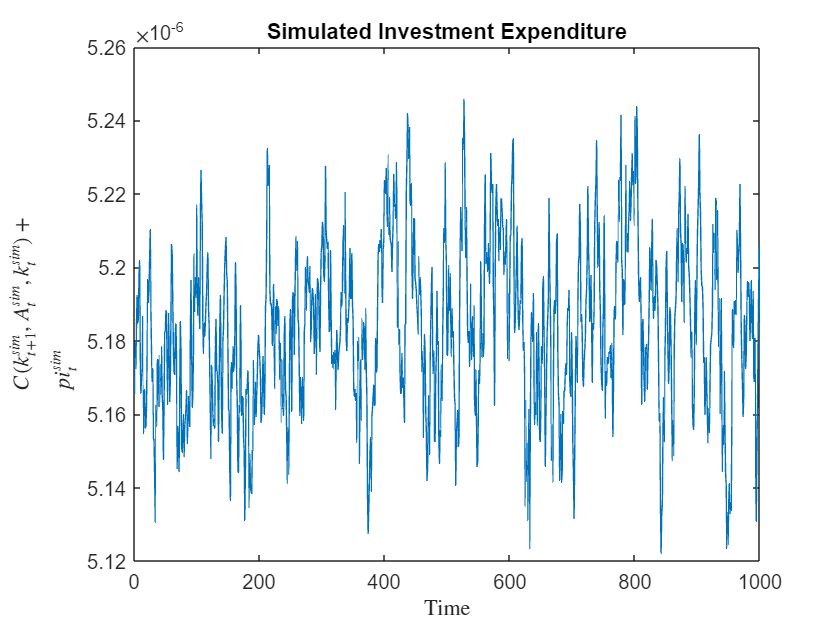

my_graph1.plot_policy(par_small, sim_small, figout, 'small_')

%my_graph1.plot_policy_3D(par_small, sol_small, figout, 'small_')

## Simulate for different values of $\gamma$ and $\delta$

% Define parameter sets
gammas = [0.10, 0.15, 0.20, 0.25];
deltas = [0.05, 0.06, 0.07, 0.08];
T = 200;

% --------- 1. Fix gamma = 0.10, vary delta ----------
figure;
hold on;
legend_entries = {};
for d = 1:length(deltas)
    par = model1.setup();
    par.gamma = 0.10;
    par.delta = deltas(d);
    par = model1.gen_grids(par);
    sol = solve1.firm_problem(par);
    sim = simulate1.firm_dynamics(par, sol);
    k = mean(sim.ksim(:, 1:T), 1, 'omitnan');
    plot(1:T, k, 'LineWidth', 1.5)
    legend_entries{end+1} = sprintf('\\delta = %.2f', deltas(d));
end

------------Beginning Value Function Iteration.------------

Iteration: 25

Converged in 41 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25

Converged in 46 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25
Iteration: 50

Converged in 50 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25
Iteration: 50

Converged in 53 iterations.

------------End of Value Function Iteration.------------


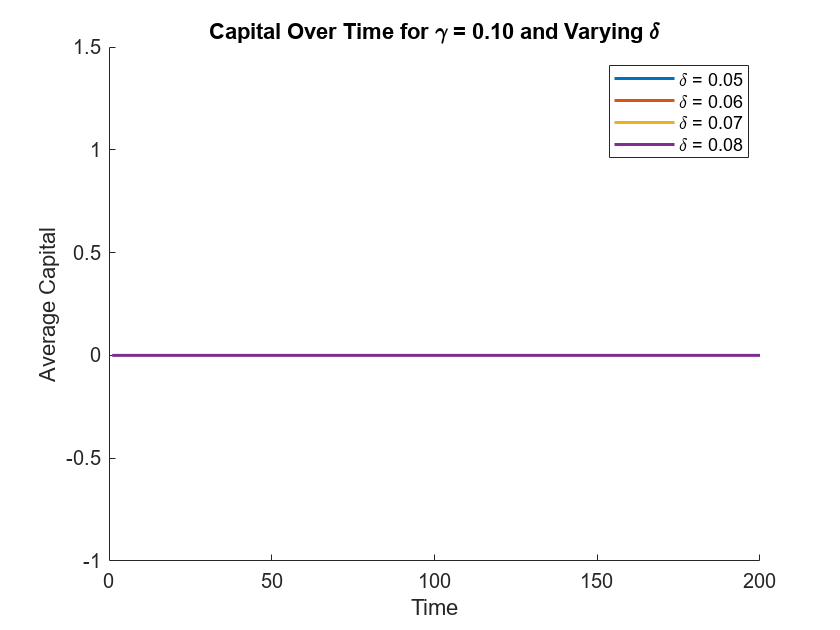

title('Capital Over Time for \gamma = 0.10 and Varying \delta')
xlabel('Time')
ylabel('Average Capital')
legend(legend_entries, 'Location', 'best')
saveas(gcf, fullfile(figout, 'capital_gamma0p10_varying_delta.png'))


% Repeat for investment
figure;
hold on;
for d = 1:length(deltas)
    par = model1.setup();
    par.gamma = 0.10;
    par.delta = deltas(d);
    par = model1.gen_grids(par);
    sol = solve1.firm_problem(par);
    sim = simulate1.firm_dynamics(par, sol);
    inv = mean(sim.esim(:, 1:T), 1, 'omitnan');
    plot(1:T, inv, 'LineWidth', 1.5)
end

------------Beginning Value Function Iteration.------------

Iteration: 25

Converged in 41 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25

Converged in 46 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25
Iteration: 50

Converged in 50 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25
Iteration: 50

Converged in 53 iterations.

------------End of Value Function Iteration.------------


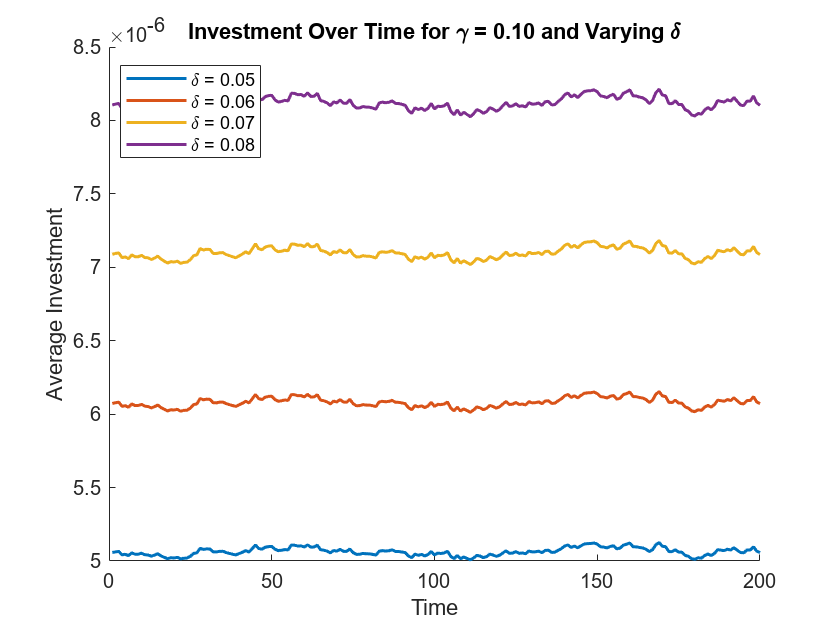

title('Investment Over Time for \gamma = 0.10 and Varying \delta')
xlabel('Time')
ylabel('Average Investment')
legend(legend_entries, 'Location', 'best')
saveas(gcf, fullfile(figout, 'investment_gamma0p10_varying_delta.png'))


% --------- 2. Fix delta = 0.08, vary gamma ----------
figure;
hold on;
legend_entries = {};
for g = 1:length(gammas)
    par = model1.setup();
    par.gamma = gammas(g);
    par.delta = 0.08;
    par = model1.gen_grids(par);
    sol = solve1.firm_problem(par);
    sim = simulate1.firm_dynamics(par, sol);
    k = mean(sim.ksim(:, 1:T), 1, 'omitnan');
    plot(1:T, k, 'LineWidth', 1.5)
    legend_entries{end+1} = sprintf('\\gamma = %.2f', gammas(g));
end

------------Beginning Value Function Iteration.------------

Iteration: 25
Iteration: 50

Converged in 53 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25
Iteration: 50

Converged in 53 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25
Iteration: 50

Converged in 53 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25
Iteration: 50

Converged in 53 iterations.

------------End of Value Function Iteration.------------


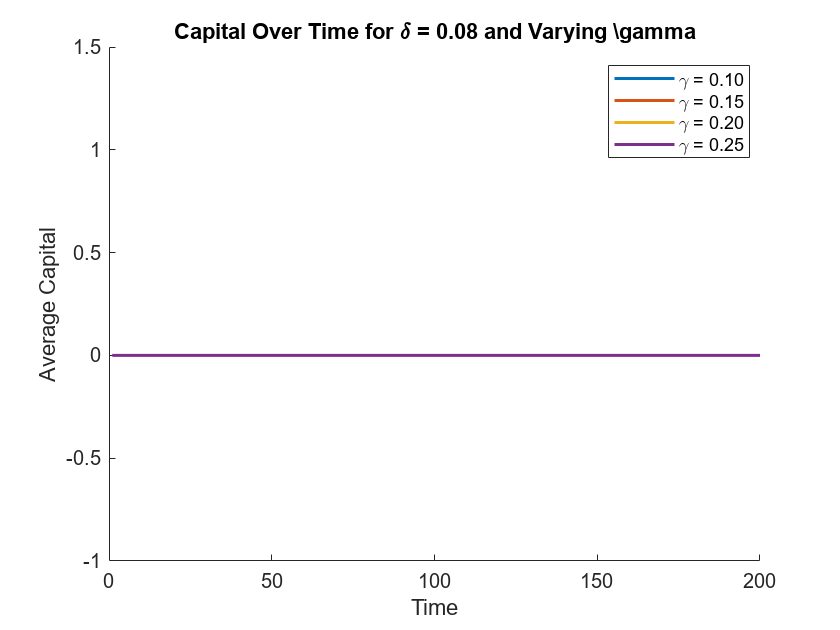

title('Capital Over Time for \delta = 0.08 and Varying \\gamma')
xlabel('Time')
ylabel('Average Capital')
legend(legend_entries, 'Location', 'best')
saveas(gcf, fullfile(figout, 'capital_delta0p08_varying_gamma.png'))


% Repeat for investment
figure;
hold on;
for g = 1:length(gammas)
    par = model1.setup();
    par.gamma = gammas(g);
    par.delta = 0.08;
    par = model1.gen_grids(par);
    sol = solve1.firm_problem(par);
    sim = simulate1.firm_dynamics(par, sol);
    inv = mean(sim.esim(:, 1:T), 1, 'omitnan');
    plot(1:T, inv, 'LineWidth', 1.5)
end

------------Beginning Value Function Iteration.------------

Iteration: 25
Iteration: 50

Converged in 53 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25
Iteration: 50

Converged in 53 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25
Iteration: 50

Converged in 53 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25
Iteration: 50

Converged in 53 iterations.

------------End of Value Function Iteration.------------


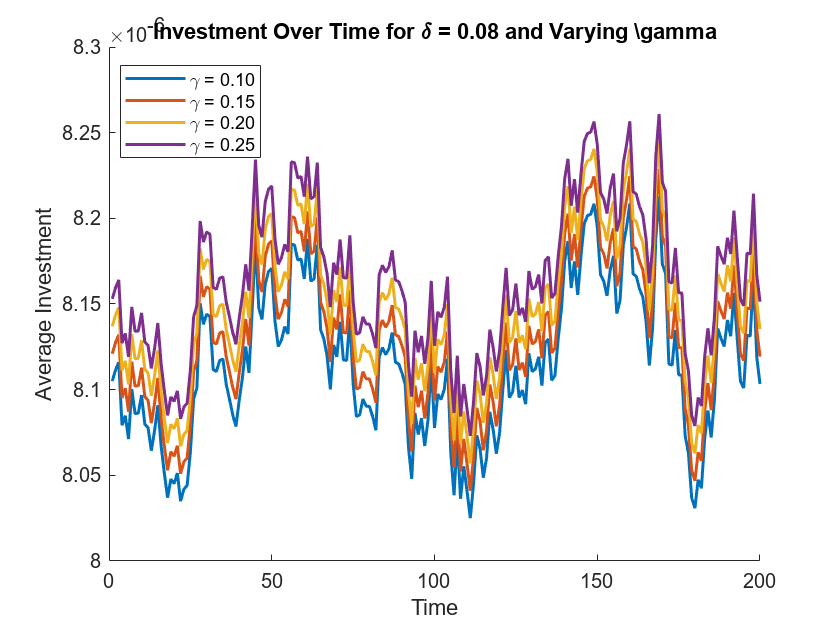

title('Investment Over Time for \delta = 0.08 and Varying \\gamma')
xlabel('Time')
ylabel('Average Investment')
legend(legend_entries, 'Location', 'best')
saveas(gcf, fullfile(figout, 'investment_delta0p08_varying_gamma.png'))


% --------- 3. Heatmap of average capital by gamma x delta ----------
avg_k = nan(length(deltas), length(gammas));
for d = 1:length(deltas)
    for g = 1:length(gammas)
        par = model1.setup();
        par.gamma = gammas(g);
        par.delta = deltas(d);
        par = model1.gen_grids(par);
        sol = solve1.firm_problem(par);
        sim = simulate1.firm_dynamics(par, sol);
        avg_k(d, g) = mean(sim.ksim(:, end), 'omitnan'); % use final period capital
    end
end

------------Beginning Value Function Iteration.------------

Iteration: 25

Converged in 41 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25

Converged in 41 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25

Converged in 41 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25

Converged in 41 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25

Converged in 46 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25

Converged in 46 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value 

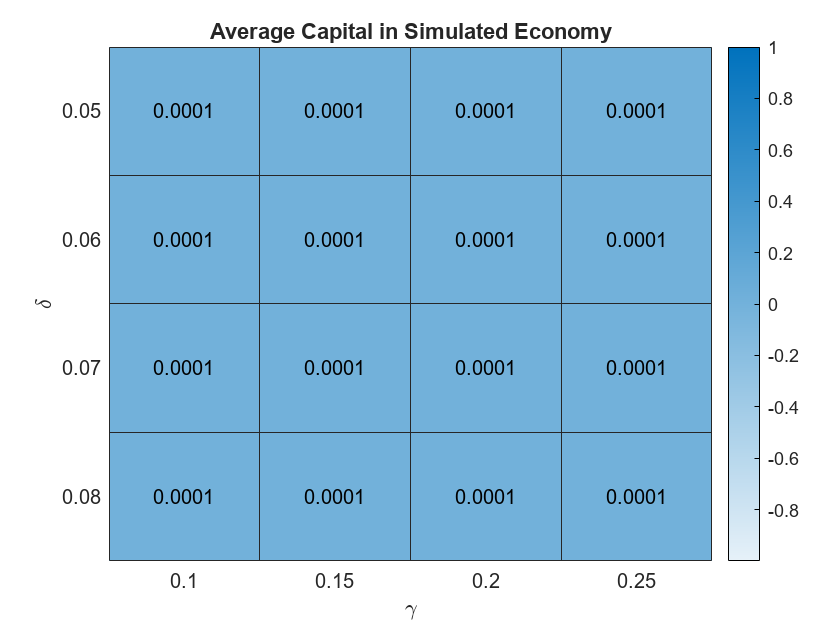

figure;
heatmap(gammas, deltas, avg_k, 'XLabel', '\gamma', 'YLabel', '\delta', ...
        'Title', 'Average Capital in Simulated Economy');
saveas(gcf, fullfile(figout, 'heatmap_avg_capital.png'))